# IIW guidelines

Applies directly for the following conditions:

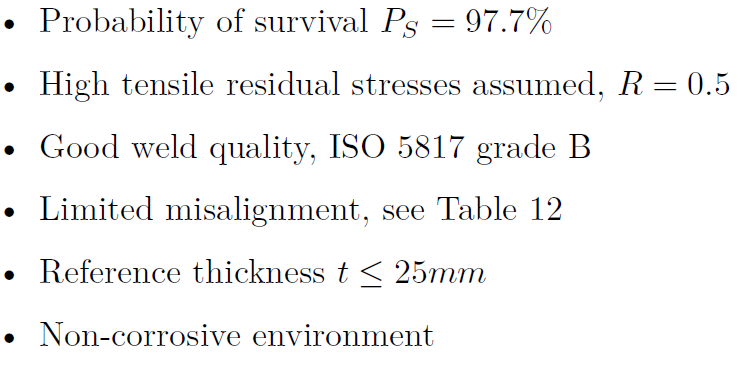

Anything else then this needs to be corrected

$k_{miss}$ er missalignment factor

$k_{env}$ er envorment  og korrrosions faktor

located at 0.4t and 1.0t away from the weld toe.

clear all
Data_E3 = struct( ... % column: 1 = DC code/stress, 2 = norminal stress, 3 = cycle life time.
    'A', [80, 216.3, 27700],...
    'B', [90, 138.2, 151200],...
    'C1',[40, 65.7, 123500],...
    'C2', [80, 49.3, 2341000],...
    'C3', [56, 1.5, 10000000])

Data_E3 = struct with fields:
     A: [80 216.3 27700]
     B: [90 138.2 151200]
    C1: [40 65.7 123500]
    C2: [80 49.3 2341000]
    C3: [56 1.5 10000000]



N_C = 2e6;
N_D = 1e7;
m1 = 3;
m2 = 5;
y_Mf = 1.54;
t = 8.5; %mm
t_04 = t * 0.4

t_04 =           3.4


A er en type **a** toe

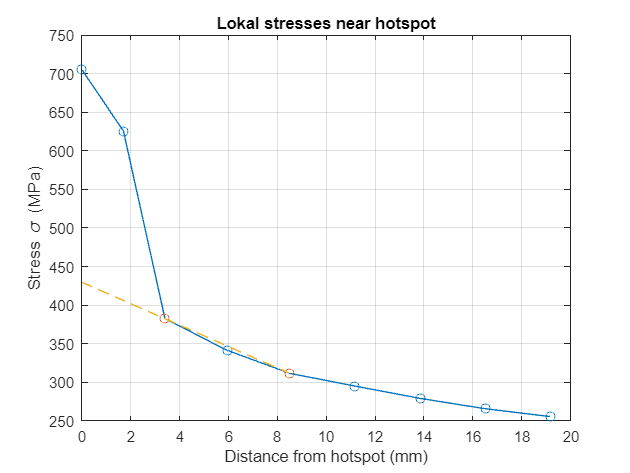

% Read the CSV file
data = readmatrix('A_data_plot.csv');	  

% Extract the relevant columns
x = data(7:end,3) - data(7,3); % x mm fra hot spot 0 placeres i hotspot
y = data(7:end,2); % stress data for point

%make t values
x_04 = x(3);
x_1 = x(5);
S_t04 = y(3);
S_t1 = y(5);

x_plot = [x_04; x_1];
y_plot = [S_t04; S_t1];

xi = linspace(0,x_1,10); 
yi = interp1(x_plot,y_plot,xi, 'linear', 'extrap'); 

% Create the plot
figure;
plot(x, y, '-o');
hold on
scatter(x_plot,y_plot)
plot(xi,yi, '--')
xlabel('Distance from hotspot (mm)');
ylabel('Stress \sigma (MPa)');
title('Lokal stresses near hotspot');
xticks(x(1):2:x(end)+1)
grid on;
hold off

Udregninger

format shortg

S_hs = 1.67 * S_t04 - 0.67 * S_t1

S_hs =        429.74


FAT = 100;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    5.4761e+11


S_D = super(C1, N_D, sym('S'), m1)

S_D =        37.974



if  S_hs > S_D
    N_life = super(C1, sym('N'), S_hs, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_hs, m2)
end

N_life =        6900.2



Data_IIW = struct( ... % column: 1 = DC code/stress, 2 = norminal stress, 3 = cycle life time.
    'A', [FAT, S_hs, N_life])

Data_IIW = struct with fields:
    A: [100 429.74 6900.2]


B er type **d** butt weld

(not needed)

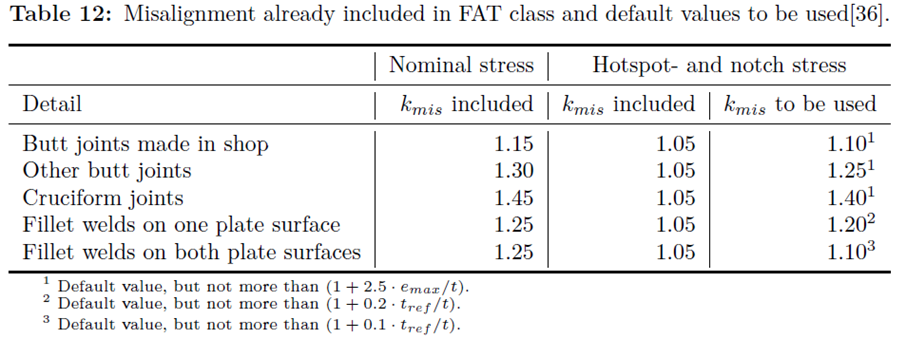

format shortg
S_B = 137.8;

k_miss = 1.1;
FAT = 100 / k_miss;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    4.1142e+11


S_D = super(C1, N_D, sym('S'), m1)

S_D =        34.522



if  S_hs > S_D
    N_life = super(C1, sym('N'), S_B, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_B, m2)
end

N_life =    1.5723e+05



Data_IIW.B = [FAT, S_B, N_life]

Data_IIW = struct with fields:
    A: [100 429.74 6900.2]
    B: [90.909 137.8 1.5723e+05]


C1 er (**c**) – root

% Read the CSV file
data = readmatrix('C1_data.csv')

data =           NaN          NaN          NaN         2024          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
            1         90.9         1925       4.0014       99.996
            2         80.8         1925       4.5863       100.59
            3         71.1         1925       5.1457       101.14
            4         62.1         1925       5.6798       101.69



% Extract the relevant columns
% x = flip(data(7,3)) - flip(data(7:end,3)) % x mm fra hot spot 0 placeres i hotspot
y = flip(data(7:end,4)) - max(data(7:end,4)); % x mm fra hot spot 0 placeres i hotspot
z = flip(data(7:end,5)) - max(data(7:end,5)); % x mm fra hot spot 0 placeres i hotspot

l = sqrt(y.^2 + z.^2)

l =             0
      0.61144
       1.3775
       2.1579
       2.9923


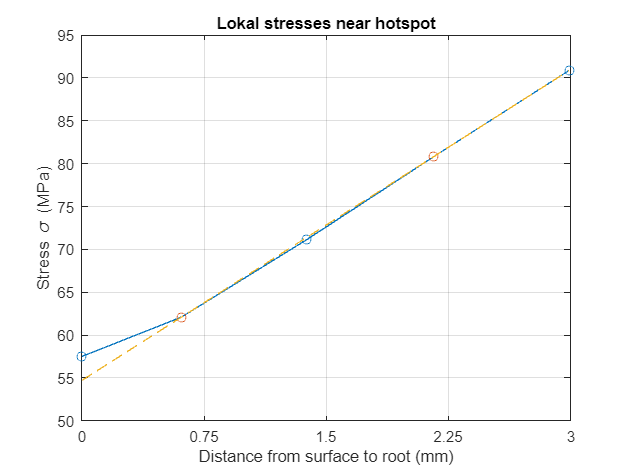

S = flip(data(7:end,2)); % stress data for point

%make t values
l_01 = l(2);
l_03 = l(4);
S_t01 = S(2);
S_t03 = S(4);

x_plot = [l_01; l_03];
y_plot = [S_t01; S_t03];

xi = linspace(0,max(l),10); 
yi = interp1(x_plot,y_plot,xi, 'linear', 'extrap'); 

% Create the plot
figure;
plot(l, S, '-o');
hold on
scatter(x_plot,y_plot)
plot(xi,yi, '--')
xlabel('Distance from surface to root (mm)');
ylabel('Stress \sigma (MPa)');
title('Lokal stresses near hotspot');
xticks(min(l):3/4:max(l)+1)
grid on;
hold off

Udregninger

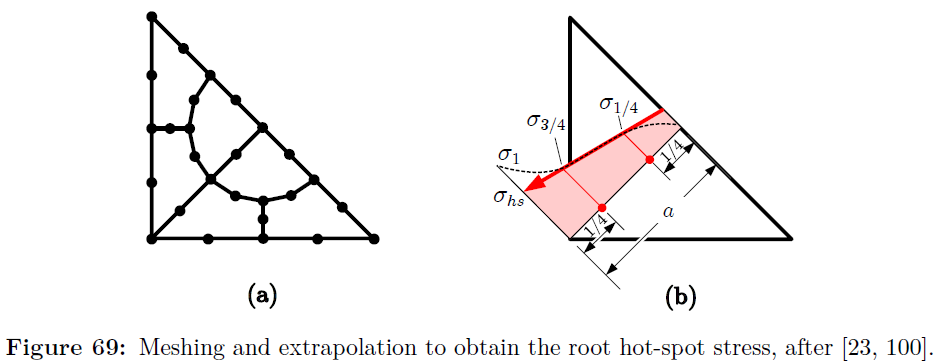

format shortg

S_hs = 1.5 * S_t03 - 0.5 * S_t01

S_hs =         90.15


FAT = 61;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =     1.243e+11


S_D = super(C1, N_D, sym('S'), m1)

S_D =        23.164



if  S_hs > S_D
    N_life = super(C1, sym('N'), S_hs, m1)
    disp('over knee')
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_hs, m2)
    disp('under knee')
end

N_life =    1.6965e+05


over knee



Data_IIW.C1 = [FAT, S_hs, N_life]

Data_IIW = struct with fields:
     A: [100 429.74 6900.2]
     B: [90.909 137.8 1.5723e+05]
    C1: [61 90.15 1.6965e+05]


C2 er **b** – da vibefinders ospå det påsvejste emne

% Read the CSV file
data = readmatrix('C2_data.csv','DecimalSeparator',',', Delimiter=';',ThousandsSeparator='.')	  

data =           NaN          NaN          NaN         2024          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
        14866        238.9         1925            4       104.24
        19945        198.2         1925            4       106.24
        14837        106.1         1925            4       108.24
        19946         93.1         1925            4       110.24



% Extract the relevant columns
z = data(7:end,5) - data(7,5) % x mm fra hot spot 0 placeres i hotspot

z =      0
     2
     4
     6
     8
    10
    12


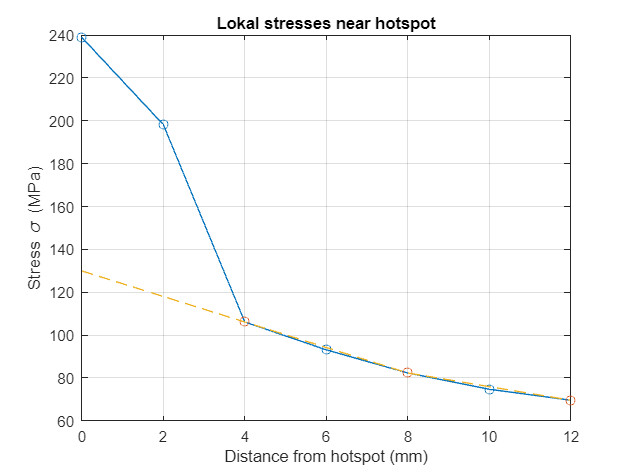

S = data(7:end,2); % stress data for point

%make t values
z_04 = z(3);
z_08 = z(5);
z_12 = z(7);
S_04 = S(3);
S_08 = S(5);
S_12 = S(7);

x_plot = [z_04; z_08; z_12];
y_plot = [S_04; S_08; S_12];

xi = linspace(0,z_12,10); 
yi = interp1(x_plot,y_plot,xi, 'linear', 'extrap'); 

% Create the plot
figure;
plot(z, S, '-o');
hold on
scatter(x_plot,y_plot)
plot(xi,yi, '--')
xlabel('Distance from hotspot (mm)');
ylabel('Stress \sigma (MPa)');
title('Lokal stresses near hotspot');
xticks(z(1):2:z(end)+1)
grid on;
hold off

Udregninger

format shortg

S_hs = 3 * S_04 - 3 * S_08 + S_12

S_hs =           141


FAT = 90;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =     3.992e+11


S_D = super(C1, N_D, sym('S'), m1)

S_D =        34.177



if  S_hs > S_D
    N_life = super(C1, sym('N'), S_hs, m1)
    disp('over knee')
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_hs, m2)
    disp('under knee')
end

N_life =    1.4241e+05


over knee



Data_IIW.C2 = [FAT, S_hs, N_life]

Data_IIW = struct with fields:
     A: [100 429.74 6900.2]
     B: [90.909 137.8 1.5723e+05]
    C1: [61 90.15 1.6965e+05]
    C2: [90 141 1.4241e+05]


C3 er **a** toe

% Read the CSV file
data = readmatrix('C3_data.csv','DecimalSeparator',',', Delimiter=';',ThousandsSeparator='.')	  

data =           NaN          NaN          NaN         2024          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          NaN          NaN          NaN          NaN
        14861        113.8       1920.8            0          100
        19018         64.2       1919.1            0          100
        14839         37.5       1917.4            0          100
        19017         22.5       1916.1            0          100


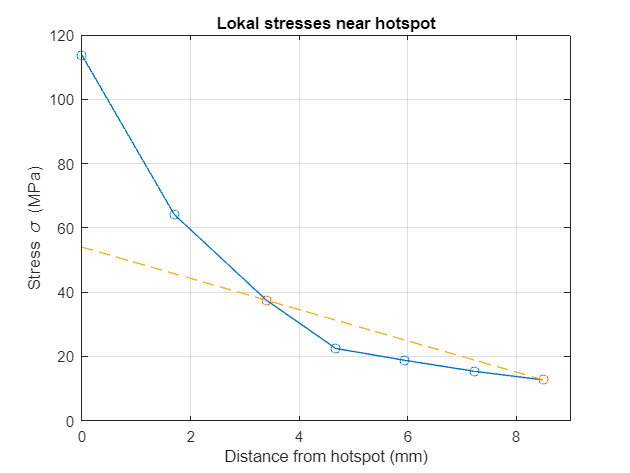


% Extract the relevant columns
x = max(data(7:end,3)) - data(7:end,3); % x mm fra hot spot 0 placeres i hotspot
y = data(7:end,2); % stress data for point

%make t values
x_04 = x(3);
x_1 = x(end);
S_t04 = y(3);
S_t1 = y(end);

x_plot = [x_04; x_1];
y_plot = [S_t04; S_t1];

xi = linspace(0,x_1,10); 
yi = interp1(x_plot,y_plot,xi, 'linear', 'extrap'); 

% Create the plot
figure;
plot(x, y, '-o');
hold on
scatter(x_plot,y_plot)
plot(xi,yi, '--')
xlabel('Distance from hotspot (mm)');
ylabel('Stress \sigma (MPa)');
title('Lokal stresses near hotspot');
xticks(min(x):2:max(x)+2)
grid on;
hold off

Udregninger

format shortg

S_hs = 1.67 * S_t04 - 0.67 * S_t1

S_hs =        54.116


FAT = 100;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    5.4761e+11


S_D = super(C1, N_D, sym('S'), m1)

S_D =        37.974



if  S_hs > S_D
    N_life = super(C1, sym('N'), S_hs, m1)
    disp('over knee')
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_hs, m2)
    disp('under knee')
end

N_life =    3.4553e+06


over knee



Data_IIW.C3 = [FAT, S_hs, N_life]

Data_IIW = struct with fields:
     A: [100 429.74 6900.2]
     B: [90.909 137.8 1.5723e+05]
    C1: [61 90.15 1.6965e+05]
    C2: [90 141 1.4241e+05]
    C3: [100 54.116 3.4553e+06]


Data_IIW

Data_IIW = struct with fields:
     A: [100 429.74 6900.2]
     B: [90.909 137.8 1.5723e+05]
    C1: [61 90.15 1.6965e+05]
    C2: [90 141 1.4241e+05]
    C3: [100 54.116 3.4553e+06]


Data_E3

Data_E3 = struct with fields:
     A: [80 216.3 27700]
     B: [90 138.2 151200]
    C1: [40 65.7 123500]
    C2: [80 49.3 2341000]
    C3: [56 1.5 10000000]


datas_E3 = [Data_E3.A; Data_E3.B; Data_E3.C1; Data_E3.C2; Data_E3.C3]

datas_E3 =            80        216.3        27700
           90        138.2    1.512e+05
           40         65.7    1.235e+05
           80         49.3    2.341e+06
           56          1.5        1e+07


datas_IIW = [Data_IIW.A; Data_IIW.B; Data_IIW.C1; Data_IIW.C2; Data_IIW.C3]

datas_IIW =           100       429.74       6900.2
       90.909        137.8   1.5723e+05
           61        90.15   1.6965e+05
           90          141   1.4241e+05
          100       54.116   3.4553e+06


for i = 1:5
    N_IIW(i) = datas_IIW(i,3);
    N_E3(i) = datas_E3(i,3);
    Ss_IIW(i) = datas_IIW(i,2);
    Ss_E3(i) = datas_E3(i,2);
end
% N_IIW = N_IIW'
% N_E3 = N_E3'
% Ss_IIW = Ss_IIW' 
% Ss_E3 = Ss_E3'

tab = table([N_IIW; N_E3; Ss_IIW; Ss_E3]', ...
    RowNames={'A', 'B', 'C1', 'C2', 'C3'})%,...

tab = 5×1 table
                                  Var1                        
          ____________________________________________________

    A         6900.2         27700        429.74         216.3
    B     1.5723e+05     1.512e+05         137.8         138.2
    C1    1.6965e+05     1.235e+05         90.15          65.7
    C2    1.4241e+05     2.341e+06           141          49.3
    C3    3.4553e+06         1e+07        54.116           1.5


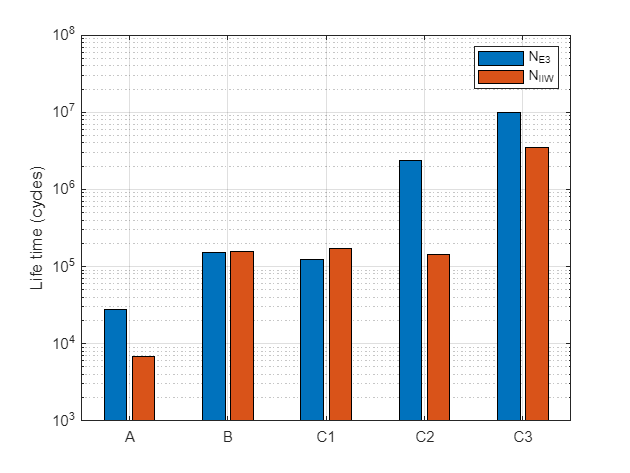

    % VariableNames={'N_IIW', 'N_E3', 'S_IIW', 'S_E3', 'last'})


figure
bar_data = [N_E3; N_IIW]';
bar(bar_data)
% Sætter y-aksen til logaritmisk skala
set(gca, 'YScale', 'log');
ylim([1e3 1e8]);
xticks(1:length(N_IIW)); % Sørg for, at der er lige så mange tick-mærker som data-punkter
xticklabels({'A', 'B', 'C1', 'C2', 'C3'}); % Tilpas x-aksen labels
ylabel('Life time (cycles)')

% Tilføj grid for bedre læsbarhed
grid on;
legend('N_E3', 'N_IIW')

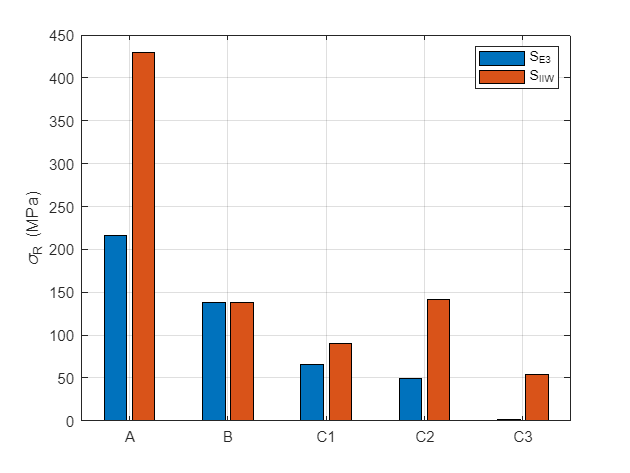



figure
bar_data = [Ss_E3; Ss_IIW]';
bar(bar_data)
xticks(1:length(Ss_IIW)); % Sørg for, at der er lige så mange tick-mærker som data-punkter
xticklabels({'A', 'B', 'C1', 'C2', 'C3'}); % Tilpas x-aksen labels
ylabel('\sigma_R (MPa)')

% Tilføj grid for bedre læsbarhed
grid on;
legend('S_E3', 'S_IIW')